close all
clear
clc

syms x y z real
syms R W real positive
syms mu mu_m eta U Ha real positive
syms pi

syms n integer positive

lambda_n=(2*n+1)*pi/(2*W/R)

$$lambda\_n = \frac{\pi \,R\,\left(2\,n+1\right)}{2\,W}$$

alfa_n=sqrt(lambda_n^2+Ha^2/2+Ha*sqrt(lambda_n^2+Ha^2/4))

$$alfa\_n = \sqrt{\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}+\frac{{\mathrm{Ha}}^{2}}{2}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}$$

beta_n=sqrt(lambda_n^2+Ha^2/2-Ha*sqrt(lambda_n^2+Ha^2/4))

$$beta\_n = \sqrt{\frac{{\mathrm{Ha}}^{2}}{2}-\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}$$

gamma_n=+beta_n*(lambda_n^2-alfa_n^2)*sinh(alfa_n)*cosh(beta_n)...
        -alfa_n*(lambda_n^2-beta_n^2)*sinh(beta_n)*cosh(alfa_n)

$$gamma\_n = -\cosh\left(\sqrt{\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}+\frac{{\mathrm{Ha}}^{2}}{2}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}\right)\,\sinh\left(\sqrt{\frac{{\mathrm{Ha}}^{2}}{2}-\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}\right)\,\left(\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}-\frac{{\mathrm{Ha}}^{2}}{2}\right)\,\sqrt{\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}+\frac{{\mathrm{Ha}}^{2}}{2}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}-\cosh\left(\sqrt{\frac{{\mathrm{Ha}}^{2}}{2}-\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}\right)\,\sinh\left(\sqrt{\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}+\frac{{\mathrm{Ha}}^{2}}{2}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}\right)\,\left(\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}+\frac{{\mathrm{Ha}}^{2}}{2}\right)\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{2}-\mathrm{Ha}\,\sqrt{\frac{{\mathrm{Ha}}^{2}}{4}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}+\frac{R^{2}\,\pi^{2}\,{\left(2\,n+1\right)}^{2}}{4\,W^{2}}}$$

A_n=+2*alfa_n*(lambda_n^2-beta_n^2)/(gamma_n*lambda_n^3*W/R)*sinh(beta_n)*sin(lambda_n*W/R)

B_n=-2*beta_n*(lambda_n^2-alfa_n^2)/(gamma_n*lambda_n^3*W/R)*sinh(alfa_n)*sin(lambda_n*W/R)

u_n=A_n*cosh(alfa_n*y/R)+B_n*cosh(beta_n*y/R)

b_n=A_n*(lambda_n^2-alfa_n^2)/alfa_n*sinh(alfa_n*y/R)+B_n*(lambda_n^2-beta_n^2)/beta_n*sinh(beta_n*y/R)


fv_x=u_n*cos(lambda_n*z/R);
fb_x=b_n*cos(lambda_n*z/R);

pi=3.141592653589793;
R=1; W=10; Ha=0.001;
mu=1; mu_m=1; eta=1; U=1;
Nplot=100; NFourier=100;
[y,z]=meshgrid(linspace(-R,+R,Nplot),linspace(-W,+W,Nplot));
for n=0:NFourier
  v_x_aux(:,:,n+1)=eval(fv_x);
end
v_x=3/2*U*((W/R)^2-(z/R).^2+2*sum(v_x_aux,3));
max(max(abs(v_x)))

ans = 1.4998

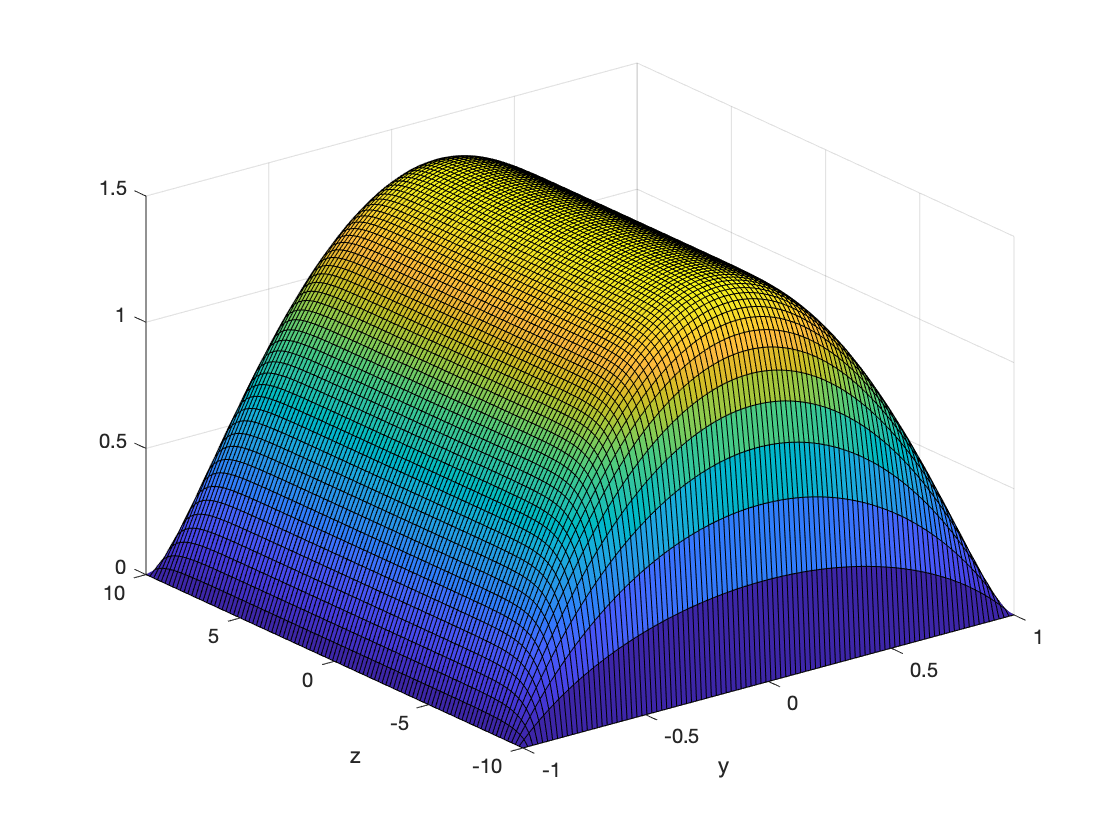

figure; surf(y,z,v_x); xlabel('y'); ylabel('z');


for n=0:NFourier
  b_x_aux(:,:,n+1)=eval(fb_x);
end
b_x=3*sqrt(mu*mu_m/eta)*U*sum(b_x_aux,3)*Ha^(-1);
max(max(abs(b_x)))

ans = 1.9245e-04

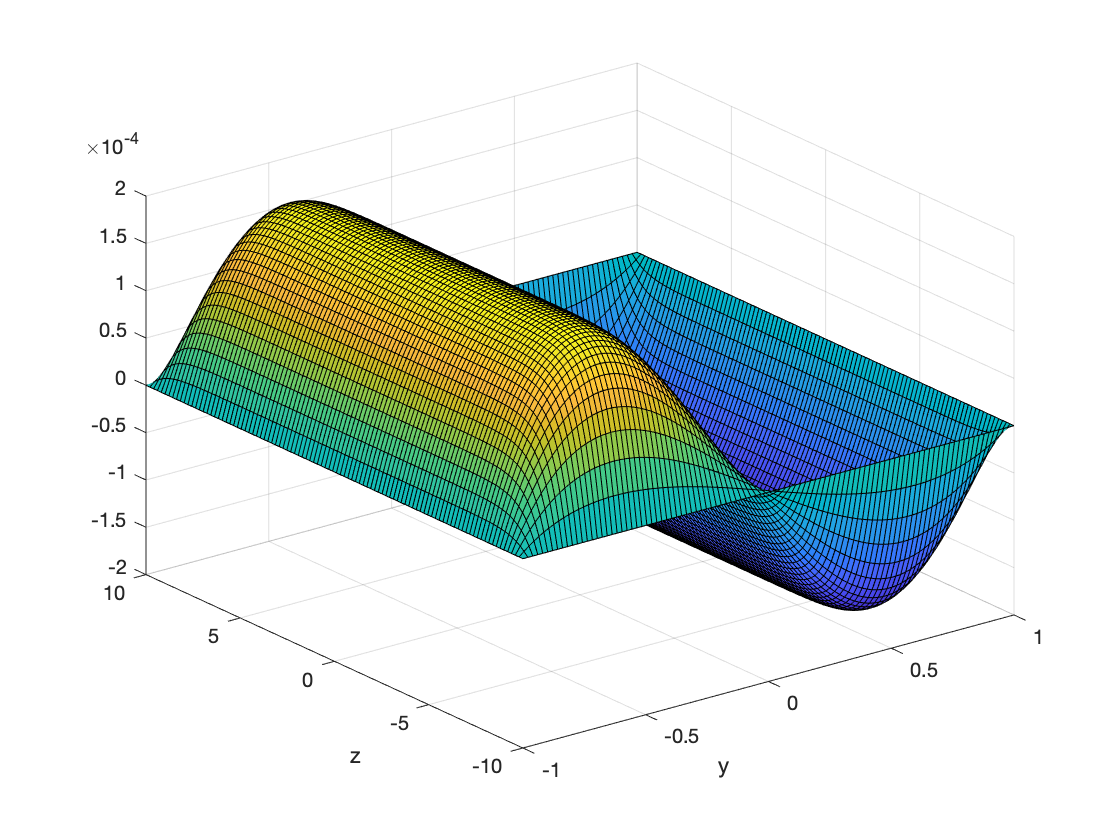

figure; surf(y,z,b_x); xlabel('y'); ylabel('z');